# ASSIGNMENT 2

*Instructor: Dr Rizwan Ahmad*

*Prepared by: Ali Hassan*

***Author: Mahnoor Anjum***

***Registration Number: 00000330720***

***Class: MSEE-TCN-2K20***

## **Question No 1:**

Consider a scenario where Source (S) wants to communicate with the destination (D). The link between S to D use IEEE 802.11g (802.11g is a Wi-Fi standard developed by the IEEE for transmitting data over a wireless network) for communication. The SNR for S to D link is varied from 0 to 50 dB. Calculate the capacity of that link. Plot the SNR vs. Capacity of the link.

syms SNR 
% reference for bandwidth 
% https://en.wikipedia.org/wiki/IEEE_802.11g-2003
B = 20* 10^6; % 20MHz
% SNR_watts = 10^(SNR/10);
shannon_capacity = B * log2(1 + db2pow(SNR))

$$shannon\_capacity = \frac{20000000\,\log\left(10^{\mathrm{SNR}/10}+1\right)}{\log\left(2\right)}$$

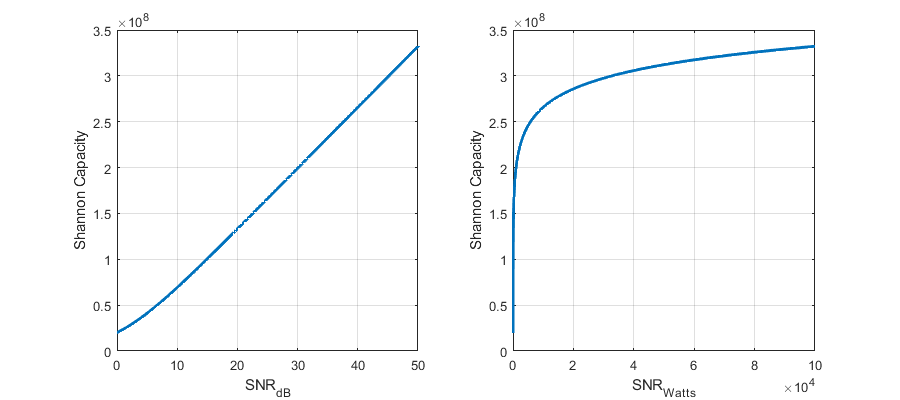


ins  = 0:1/10:50; % dB
outs = subs(shannon_capacity, SNR, ins);
clf;
set(gcf, 'Position', [100 100 900 400]);
subplot(121), hold on, box on, grid on,
plot((ins), outs, 'LineWidth', 2);
xlabel("SNR_d_B");
ylabel("Shannon Capacity");
subplot(122), hold on, box on, grid on,
plot(db2pow(ins), outs, 'LineWidth', 2);
xlabel("SNR_W_a_t_t_s");
ylabel("Shannon Capacity");

## **Question No 2:**

Consider a scenario where the Source (S) node wants to communicate with the destination (D) nodes. S to D uses IEEE 802.11 g use for communication. The distance between S to D is 100m. Consider the Dense Urban environment and the transmit power is varied from 0 to 50 dBm. Consider the channel link coefficient between S to D is Rayleigh fading and noise is AWGN.  Generate 1000 samples of a Rayleigh random variable R with E{R^2}=1. Remember that R = |X+jY|, where X and Y are zero-mean, independent Gaussian random variables (r.v). Your Gaussian r.v. X and Y (produced by randn command) must each have equal variance equal to ½.

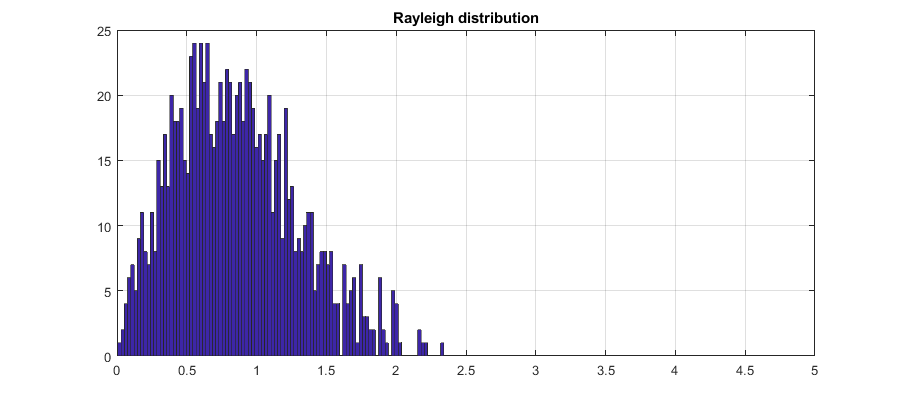

samples = 1000;
sigma = sqrt(0.5);
X = sigma*randn(1,samples);
Y = sigma*randn(1,samples);
R = sqrt(X.^2 + Y.^2);
clf;hist(R, 100); hold on, grid on, box on, xlim([0, 5]), title("Rayleigh distribution")

### Plot the Rayleigh random variable samples in a stem plot

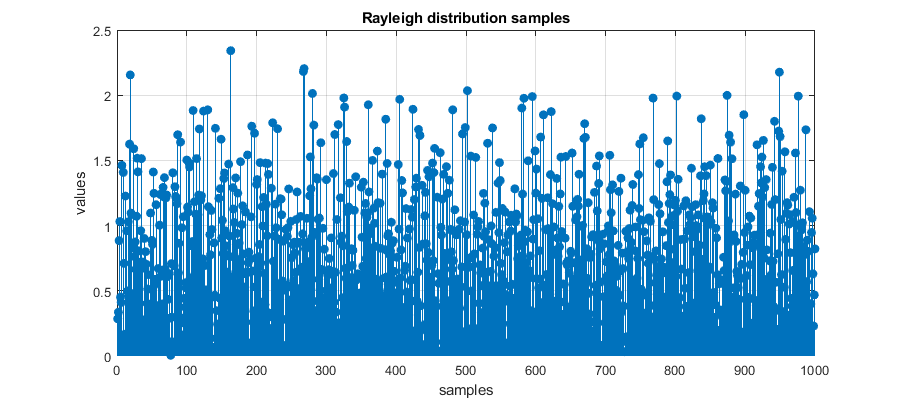

clf; hold on, box on, grid on,  xlabel("samples"), ylabel("values"),
stem(1:samples,R, "filled"); title("Rayleigh distribution samples")

### Plot the transmit power of S node vs. received power at D node. *(Hint: For calculation of the received power use Friis Equation)*

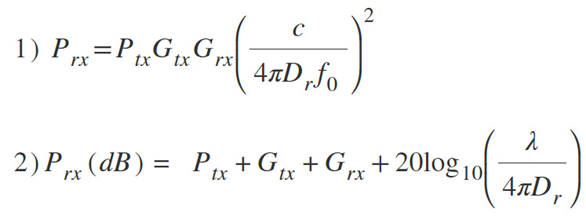

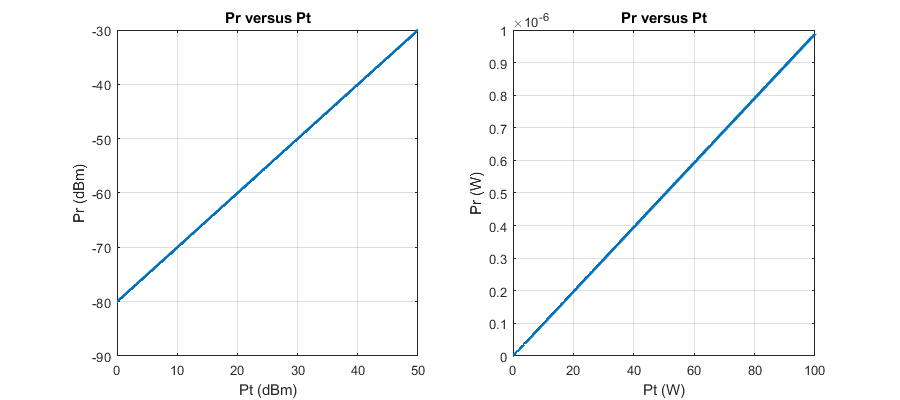

% Friis equation 
% frequency reference https://en.wikipedia.org/wiki/IEEE_802.11g-2003
clear
f  = 2.4 * 10^9; % 2.4GHz
c = physconst('LightSpeed');
lambda = c / f;
d = 100;
syms Pt 
Gt = 1; % unity gain
Gr = 1; % unity gain

Pt_Watts = 10^(Pt/10)/(10^3);
Pr = Pt_Watts* Gt * Gr * ((lambda/(4*pi*d))^2);

ins  = 0:1/50:50; % dBm
outs = subs(Pr, Pt, ins);
outs = 10*log10(outs/(10^-3));
clf, subplot(121), hold on, box on, grid on;
plot(ins, outs, 'LineWidth', 2);
title("Pr versus Pt");
xlabel("Pt (dBm)");
ylabel("Pr (dBm)");
subplot(122), hold on, box on, grid on;
plot(db2pow(ins-30), db2pow(outs-30), 'LineWidth', 2);
title("Pr versus Pt");
xlabel("Pt (W)");
ylabel("Pr (W)");

### *Plot the transmit power of S node vs. path loss *

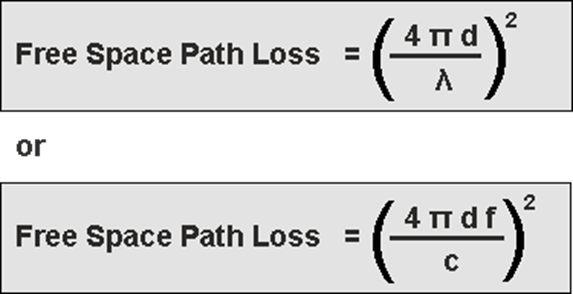

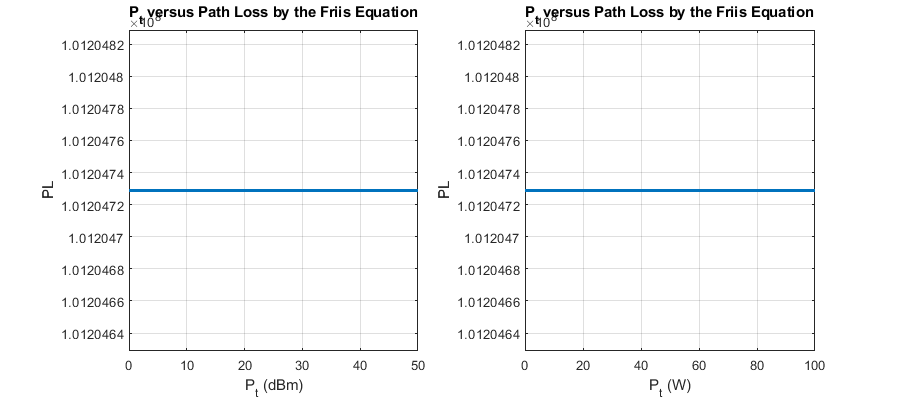

% Friis equation 
% frequency reference https://en.wikipedia.org/wiki/IEEE_802.11g-2003
clear;
f  = 2.4 * 10^9; % 2.4GHz
c = physconst('LightSpeed');
lambda = c / f;
d = 100;
Gt = 1; % unity gain
Gr = 1; % unity gain
PL = (4*pi*d/lambda)^2;
Pt  = 0:1/10:50; % dBm
PL = PL + zeros(1, length(Pt));

clf, subplot(121), hold on, box on, grid on, ylim([PL(1)-100, PL(1)+100]);
plot(Pt, PL, 'LineWidth', 2);
title("P_t versus Path Loss by the Friis Equation");
xlabel("P_t (dBm)");
ylabel("PL");
subplot(122), hold on, box on, grid on, ylim([PL(1)-100, PL(1)+100]);
plot(db2pow(Pt-30), PL, 'LineWidth', 2);
title("P_t versus Path Loss by the Friis Equation");
xlabel("P_t (W)");
ylabel("PL");

### Plot the transmit power of S node vs. SNR of the link

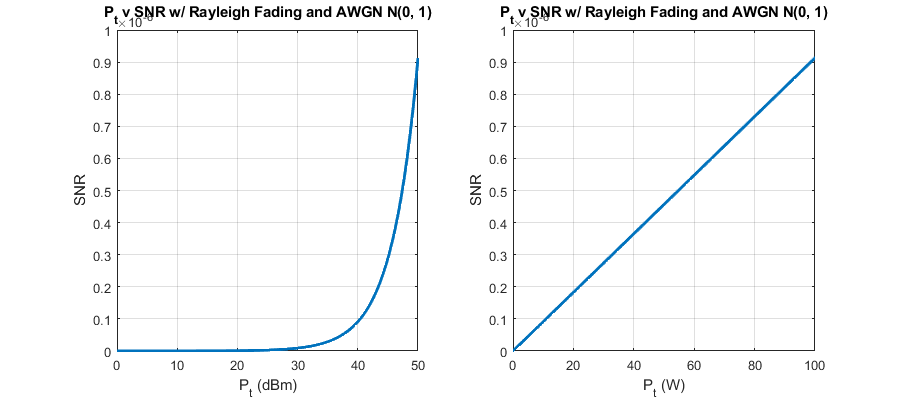

clear;
samples = 1000;
Gt = 1;  Gr = 1; d = 100;
f  = 2.4 * 10^9; c = physconst('LightSpeed'); lambda = c / f;
L  = (4*pi*d/lambda)^2;
sigma = sqrt(0.5); X = sigma*randn(1,samples); Y = sigma*randn(1,samples);
R = sqrt(X.^2 + Y.^2);
Pt  = 0:1/10:50; % dBm
Pt_Watts = 10.^(Pt./10)/(10^3);
% Add AWGN
Noise = randn(1,samples);
% Noise Power is the Mean Squared of the signal i.e. sum(R.^2) / length(R);
N = rms(Noise)^2;
% Since E{R^2} = 1
F = rms(R)^2;
% Pr (dB) = Pt + Gt + Gr + Multipath Fading + Noise - Path loss 
Pr = Pt_Watts* Gt * Gr * F * N / L;
% dBm to Watts
SNR = Pr./N;
clf, subplot(121), hold on, box on, grid on;
plot(Pt, SNR, 'LineWidth', 2);
title("P_t v SNR w/ Rayleigh Fading and AWGN N(0, 1)");
xlabel("P_t (dBm)");
ylabel("SNR");
subplot(122), hold on, box on, grid on;
plot(Pt_Watts, SNR, 'LineWidth', 2);
title("P_t v SNR w/ Rayleigh Fading and AWGN N(0, 1)");
xlabel("P_t (W)");
ylabel("SNR");

### Plot the transmit power vs. Capacity of the link

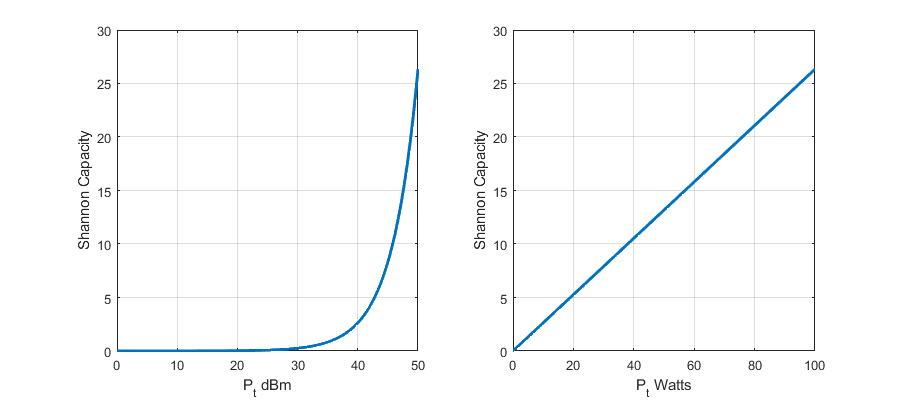

% reference for bandwidth 
% https://en.wikipedia.org/wiki/IEEE_802.11g-2003
B = 20* 10^6; % 20MHz
% SNR_watts = 10^(SNR/10);
C = B * log2(1 + SNR);

clf;
set(gcf, 'Position', [100 100 900 400]);
subplot(121), hold on, box on, grid on,
plot(Pt, C, 'LineWidth', 2);
xlabel("P_t dBm");
ylabel("Shannon Capacity");
subplot(122), hold on, box on, grid on,
plot(db2pow(Pt-30), C, 'LineWidth', 2);
xlabel("P_t Watts");
ylabel("Shannon Capacity");